## Задание 1. Синтез регулятора с заданной степенью устойчивости.

function [eigenvalues, controllability_result] = analyze_controllability(A, B)
    eigenvalues = eig(A);
    controllability_result = true;
    
    disp('Eigenvalues of A:');
    disp(eigenvalues);
    
    for i = 1:length(eigenvalues)
        H = [eigenvalues(i) * eye(size(A)) - A, B]
        rank_H = rank(H)
        fprintf('Eigenvalue %d %di', real(eigenvalues(i)), imag(eigenvalues(i)));
        if rank_H < size(A, 1)
            controllability_result = false;
            fprintf(' is not controllable.\n');
        else
            fprintf(' is controllable.\n');
        end
    end
    
    if controllability_result
        disp('The system is fully controllable.');
    else
        disp('The system is not fully controllable.');
    end
end

A=[3 5 4;
    -2 -4 -5;
    2 2 3];
B=[2;-1;1];

analyze_controllability(A, B);

Eigenvalues of A:
   2.0000 + 1.0000i
   2.0000 - 1.0000i
  -2.0000 + 0.0000i



H =   -1.0000 + 1.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   2.0000 + 0.0000i   6.0000 + 1.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
  -2.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 + 1.0000i   1.0000 + 0.0000i


rank_H = 3

Eigenvalue 2 1.000000e+00i is controllable.


H =   -1.0000 - 1.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   2.0000 + 0.0000i   6.0000 - 1.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
  -2.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 - 1.0000i   1.0000 + 0.0000i


rank_H = 3

Eigenvalue 2 -1.000000e+00i is controllable.


H =    -5.0000   -5.0000   -4.0000    2.0000
    2.0000    2.0000    5.0000   -1.0000
   -2.0000   -2.0000   -5.0000    1.0000


rank_H = 2

Eigenvalue -2.000000e+00 0i is not controllable.
The system is not fully controllable.


### Степень устойчивости 1

function [K] = syntK(A, B, a)
    cvx_begin sdp
        variable P(size(A, 1), size(A, 1))
        variable Y(size(B, 2), size(B, 1))
        P > 0.0001*eye(size(A, 1));
        P*A'+A*P+2*a*P+Y'*B'+B*Y <= 0;
    cvx_end
    K = Y*inv(P);
end

K1 = syntK(A, B, 2)

 
Calling SDPT3 4.0: 15 variables, 6 equality constraints
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  =  6,   num. of sdp  blk  =  2
 dim. of free   var  =  3 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.7e+02|5.0e+01|1.3e+03| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.915|0.857|1.5e+01|7.3e+00|1.1e+02| 0.000000e+00  2.541325e-03| 0:0:01| chol  1  1 
 2|0.882|0.717|1.8e+00|2.1e+00|3.1e+01| 0.000000e+00  2.025144e-03| 0:0:01| chol  1  1 
 3|0.940|0.949|1.1e-01|1.1e-01|1.6e+00| 0.000000e+00  2.370570e-04| 0:0:01| 

K1 =     3.3536    2.1216  -17.9071


K1 = [3.3536 2.1216 -17.9071];

function [K] = syntKmin(A, B, a, x0)
    cvx_begin sdp
        variable P(size(A, 1), size(A, 1)) symmetric
        variable Y(size(B, 2), size(B, 1))
        variable mumu
        minimize mumu
        P >= 0.000001*eye(size(A, 1));
        P*A'+A*P+2*a*P+Y'*B'+B*Y <= 0;
        [P x0;
         x0' 1] >= 0.000001*eye(size(A, 1) + 1);
        [P Y';
         Y mumu] >= 0.000001*eye(size(A, 1) + size(B, 2));
    cvx_end
    K = Y*inv(P);
end

K2 = syntKmin(A, B, 2, [0; 0; 0])

 
Calling SDPT3 4.0: 41 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of sdp    var  = 14,   num. of sdp  blk  =  4
 dim. of free   var  =  9 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.8e+01|2.1e+02|6.7e+04| 9.997000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.940|0.930|5.9e+00|1.5e+01|1.1e+03| 8.518234e+00 -9.181422e+00| 0:0:00| chol  1  1 
 2|0.644|0.673|2.1e+00|4.9e+00|1.7e+02| 6.989065e+00 -1.746942e+01| 0:0:00| chol  1  1 
 3|0.934|0.9

K2 =    -0.1414   -0.1413   -7.8586


K2 = [-1.0712 -1.0712 -3.3288];

function [K] = syntRic(A, B, a, Q)
    syms P_ [size(A,1), size(A,1)]
    eqs = [A'*P_+P_*A-2*P_'*B*B'*P_+2*a*P_ + Q == 0];
    s = vpasolve(eqs, [P_], Random=true)
    P = [s.P_1_1 s.P_1_2;
        s.P_2_1 s.P_2_2];
    K = -B'*P;
end

function [J1, Bj, P1] = j_stuff_B(A, B)
    [P, J] = jordan(A);
    [P1, J1] = cdf2rdf(P, J);

    disp('Вещественная жорданова форма матрицы A:');
    disp(J1);

    disp('Вещественная P:');
    disp(P1);

    disp('Вещественная P^{-1}:');
    disp(inv(P1));

    disp('Новая матрица B:');
    Bj = P1\B;
    disp(Bj); 
end

[AJ, BJ, P1] = j_stuff_B(A, B)

Вещественная жорданова форма матрицы A:
    -2     0     0
     0     2    -1
     0     1     2

Вещественная P:
   -1.0000    0.7071   -0.7071
    1.0000   -1.4142         0
         0    1.4142         0

Вещественная P^{-1}:
         0    1.0000    1.0000
         0         0    0.7071
   -1.4142   -1.4142   -0.7071

Новая матрица B:
         0
    0.7071
   -2.1213



AJ =     -2     0     0
     0     2    -1
     0     1     2


BJ =          0
    0.7071
   -2.1213


P1 =    -1.0000    0.7071   -0.7071
    1.0000   -1.4142         0
         0    1.4142         0


Aj = [2 -1;
    1 2];
Bj = BJ(2:3);

K3j = syntRic(Aj, Bj, 2, eye(2))

s = struct with fields:
    P_1_1: -0.12221411745562729432413866866022
    P_2_1: -0.0055816610235245795774140087201855
    P_1_2: -0.0055816610235245795774140087201855
    P_2_2: -0.11259942934741835827981243346063


$$K3j = \left(\begin{array}{cc} 0.052734567192526777795948321249832\,\sqrt{2} & -0.16610831350936524763101164583085\,\sqrt{2} \end{array}\right)$$

K3J = [0 K3j];
K3 = K3J/P1

$$K3 = \left(\begin{array}{ccc} 0.3322166270187304952620232916617 & 0.3322166270187304952620232916617 & 0.21884288070189202542695996708068 \end{array}\right)$$

K3 = [2.1526 2.1526 -10.7037];
eig(A+B*K3)

ans =   -2.2755 + 4.3745i
  -2.2755 - 4.3745i
  -2.0000 + 0.0000i


K4j = syntRic(Aj, Bj, 2, zeros(2, 2))

s = struct with fields:
    P_1_1: -1.5596309818107062841669871491555e-46
    P_2_1: -2.8348375939467253719746956129458e-47
    P_1_2: -2.8348375939467253719746956129458e-47
    P_2_2: -7.6776419660938955173750143075713e-48


$$K4j = \left(\begin{array}{cc} 3.5458985181334433628728923263589e-47\,\sqrt{2} & 2.6577250205927835838109566033721e-48\,\sqrt{2} \end{array}\right)$$

K4J = [0 K4j];
K4 = K4J/P1

$$K4 = \left(\begin{array}{ccc} -5.3154500411855671676219132067442e-48 & -5.3154500411855671676219132067442e-48 & 3.2801260160741650044917966660217e-47 \end{array}\right)$$

K4 = [1.6 1.6 -9.6];

K4 =     1.6000    1.6000   -9.6000


eig(A+B*K4)

ans =   -2.0000 + 4.1231i
  -2.0000 - 4.1231i
  -2.0000 + 0.0000i


eig(A+B*K1)

ans =   -4.6608 + 3.6561i
  -4.6608 - 3.6561i
  -2.0000 + 0.0000i


eig(A+B*K2)

ans =   -0.2000 + 2.0010i
  -0.2000 - 2.0010i
  -2.0000 + 0.0000i


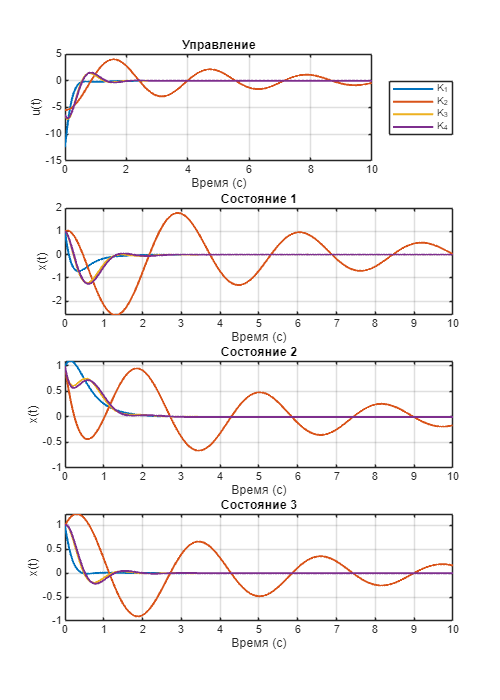

function simulate(A, B, K1, K2, K3, K4, x0, simtime, path)
    assignin('base', 'A', A);
    assignin('base', 'B', B);
    assignin('base', 'x0', x0);

    model_name = 'task1';
    load_system(model_name);

    % Simulink model name
    assignin('base', 'K', K1);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t1 = sim_out.tout;
    x1 = sim_out.yout{1}.Values.Data;
    u1 = sim_out.yout{2}.Values.Data;

    % Simulink model name
    assignin('base', 'K', K2);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t2 = sim_out.tout;
    x2 = sim_out.yout{1}.Values.Data;
    u2 = sim_out.yout{2}.Values.Data;

        % Simulink model name
    assignin('base', 'K', K3);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t3 = sim_out.tout;
    x3 = sim_out.yout{1}.Values.Data;
    u3 = sim_out.yout{2}.Values.Data;

        % Simulink model name
    assignin('base', 'K', K4);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t4 = sim_out.tout;
    x4 = sim_out.yout{1}.Values.Data;
    u4 = sim_out.yout{2}.Values.Data;

    % Plot state trajectories
    figure('Position', [0 0 500 700], 'PaperPositionMode', 'auto');

    spn = 4;

    % Plot observer error
    subplot(spn, 1, 1);
    plot(t1, u1, 'LineWidth', 1.5); hold on;
    plot(t2, u2, 'LineWidth', 1.5);
    plot(t3, u3, 'LineWidth', 1.5);
    plot(t4, u4, 'LineWidth', 1.5);
    title('Управление');
    xlabel('Время (с)');
    ylabel('u(t)');
    legend('K_1', 'K_2', 'K_3', 'K_4', 'Location', 'eastoutside');
    grid on;

    for idx=1:3
        subplot(spn, 1, idx+1);
        plot(t1, x1(:, idx), 'LineWidth', 1.5); hold on;
        plot(t2, x2(:, idx), 'LineWidth', 1.5);
        plot(t3, x3(:, idx), 'LineWidth', 1.5);
        plot(t4, x4(:, idx), 'LineWidth', 1.5);
        title(['Состояние ', int2str(idx)]);
        xlabel('Время (с)');
        ylabel('x(t)');
        %legend('K_1', 'K_2', 'K_3', 'K_4', 'Location', 'best');
        grid on;
    end
    
    % Save the figure
    exportgraphics(gcf, ['figs/', path, '.png'], 'Resolution', 500);
end

x0 = [1; 1; 1];
simulate(A, B, K1, K2, K3, K4, x0, 10, 'task10');

### Степень устойчивости 2

K1 = syntK(A, B, 0.2)

 
Calling SDPT3 4.0: 15 variables, 6 equality constraints
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  =  6,   num. of sdp  blk  =  2
 dim. of free   var  =  3 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.4e+02|4.8e+01|1.2e+03| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.947|0.800|7.6e+00|9.7e+00|1.5e+02| 0.000000e+00  1.818259e-03| 0:0:00| chol  1  1 
 2|1.000|0.881|6.3e-05|1.2e+00|1.8e+01| 0.000000e+00  3.621549e-04| 0:0:00| chol  1  1 
 3|1.000|0.989|2.4e-05|1.4e-02|2.1e-01| 0.000000e+00  4.332033e-06| 0:0:00| 

K1 =    -1.6329   -2.3204   -9.5054


K1 = [-1.6329	-2.3204	-9.5054];
K2 = syntKmin(A, B, 0.2, [0; 0; 0])

 
Calling SDPT3 4.0: 41 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of sdp    var  = 14,   num. of sdp  blk  =  4
 dim. of free   var  =  9 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.7e+01|1.6e+02|5.0e+04| 9.997000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.714|0.791|2.8e+01|3.4e+01|2.8e+03| 1.285574e+01 -1.391950e+01| 0:0:00| chol  1  1 
 2|0.483|0.885|1.4e+01|3.9e+00|5.4e+02| 1.775996e+01 -7.191190e+01| 0:0:00| chol  1  1 
 3|0.904|0.8

K2 =    -1.0712   -1.0712   -3.3288


K2 = [-1.0712	-1.0712	-3.3288];

K3j = syntRic(Aj, Bj, 0.2, eye(2))

s = struct with fields:
    P_1_1: 17.325620900691146446645457591631
    P_2_1: 2.7435263783326017790260644199468
    P_1_2: 2.7435263783326017790260644199468
    P_2_2: 1.0679320496191133774113351984462


$$K3j = \left(\begin{array}{cc} -4.5475208828466705547836321658951\,\sqrt{2} & 0.23013488526236917660397058769584\,\sqrt{2} \end{array}\right)$$

K3J = [0 K3j];
K3 = K3J/P1

$$K3 = \left(\begin{array}{ccc} -0.46026977052473835320794117539168 & -0.46026977052473835320794117539168 & -4.7776557681090397313876027535909 \end{array}\right)$$

K3 = [-0.4603 -0.4603 -4.7777];
eig(A+B*K3)

ans =   -0.6190 + 2.7483i
  -0.6190 - 2.7483i
  -2.0000 + 0.0000i


K4j = syntRic(Aj, Bj, 0.2, zeros(2, 2))

s = struct with fields:
    P_1_1: -5.247963504326465564508049858788e-44
    P_2_1: -5.4420506245009756422826261745134e-45
    P_1_2: -5.4420506245009756422826261745134e-45
    P_2_2: -3.0825601439481051690910948109547e-45


$$K4j = \left(\begin{array}{cc} 1.807674158488086435911631003217e-44\,\sqrt{2} & -1.9028149036716699324953291291753e-45\,\sqrt{2} \end{array}\right)$$

K4J = [0 K4j];
K4 = K4J/P1

$$K4 = \left(\begin{array}{ccc} 3.8056298073433398649906582583506e-45 & 3.8056298073433398649906582583506e-45 & 1.9979556488552534291611639161345e-44 \end{array}\right)$$

K4 = [ -0.704 -0.704 -3.696];
eig(A+B*K4)

ans =   -0.2000 + 2.4166i
  -0.2000 - 2.4166i
  -2.0000 + 0.0000i


eig(A+B*K1)

ans =    -1.4599
   -4.9909
   -2.0000


eig(A+B*K2)

ans =   -0.2000 + 2.0010i
  -0.2000 - 2.0010i
  -2.0000 + 0.0000i


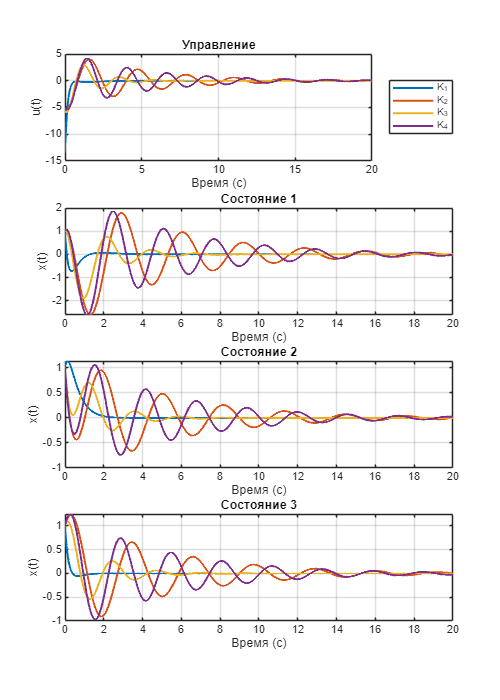

x0 = [1;1;1];
simulate(A, B, K1, K2, K3, K4, x0, 20, 'task11');

## Задание 2. Управление по выходу с заданной степенью устойчивости.

function analyze_observabillity(A, C)
    eigenvalues = eig(A);
    observ_result = true;
    
    disp('Eigenvalues of A:');
    disp(eigenvalues);
    
    for i = 1:length(eigenvalues)
        H = [eigenvalues(i) * eye(size(A)) - A; C]
        rank_H = rank(H)
        fprintf('Eigenvalue %d %di', real(eigenvalues(i)), imag(eigenvalues(i)));
        if rank_H < size(A, 1)
            observ_result = false;
            fprintf(' is not observable.\n');
        else
            fprintf(' is observable.\n');
        end
    end
    
    if observ_result
        disp('The system is fully observable.');
    else
        disp('The system is not fully observable.');
    end
end
function [L] = syntLmin(A, C, a, x0)
    cvx_begin sdp
        variable Q(size(A, 1), size(A, 1)) symmetric
        variable Y(size(C, 2), size(C, 1))
        variable mumu
        minimize mumu
        Q >= 0.0001*eye(size(A, 1));
        A'*Q + Q*A + 2*a*Q + C'*Y' + Y*C <= 0;
        [Q x0;
         x0' 1] >= 0.0001*eye(size(A, 1) + 1);
        [Q Y;
         Y' mumu*eye(2)] >= 0.0001*eye(size(A, 1) + size(C, 1));
    cvx_end
    L = inv(Q)*Y;
end
function [J1, Cj, P1] = j_stuff_C(A, C)
    [P, J] = jordan(A);
    [P1, J1] = cdf2rdf(P, J);

    disp('Вещественная жорданова форма матрицы A:');
    disp(J1);

    disp('Вещественная P:');
    disp(P1);

    disp('Вещественная P^{-1}:');
    disp(inv(P1));

    disp('Новая матрица C:');
    Cj = C*P1;
    disp(Cj);
end
function simulate_sys(A, B, C, K, L, x0, x0_hat, simtime, id)
    assignin('base', 'A', A);
    assignin('base', 'B', B);
    assignin('base', 'C', C);
    assignin('base', 'K', K);
    assignin('base', 'L', L);
    assignin('base', 'x0', x0);
    assignin('base', 'x0_hat', x0_hat);

    % Simulink model name
    model_name = 'task2';
    load_system(model_name);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t = sim_out.tout;
    x = sim_out.yout{1}.Values.Data;
    x_hat = sim_out.yout{2}.Values.Data;
    u = sim_out.yout{3}.Values.Data;
    e = x - x_hat;

    % Plot state trajectories
    figure('Position', [0 0 500 900]);

    spn = 6;

    % Plot control error
    subplot(spn, 1, 1);
    plot(t, u, 'LineWidth', 1.5);
    title('Control');
    xlabel('Time (s)');
    ylabel('u(t)');
    grid on;

    % Plot observer error
    subplot(spn, 1, 2);
    plot(t, e, 'LineWidth', 1.5);
    title('Observer Error');
    xlabel('Time (s)');
    ylabel('e(t)');
    grid on;

    % Combine x and x̂ in one plot
    for idx=1:4
        subplot(spn, 2, idx+4);
        plot(t, x(:, idx), 'LineWidth', 1.5); hold on;
        plot(t, x_hat(:, idx), '--', 'LineWidth', 1.5);
        title(['x(', num2str(idx), ') and x̂(', num2str(idx), ')']);
        if ismember(idx, [3, 4])
            xlabel('Time (s)');
        end
        if ismember(idx, [1, 3])
            ylabel('State');
        end
        legend('x', 'x̂', 'Location', 'southeast');
        grid on;
    end

    % Save the figure
    exportgraphics(gcf, ['figs/task2_', num2str(id), '.png'], 'Resolution', 500);
end

A = [5 -5 -9 3;
        -5 5 -3 9;
        -9 -3 5 5;
        3 9 5 5];
B = [2; 6; 6; 2];
C = [1 -1 1 1;
    1 3 -1 3];

analyze_controllability(A, B);

Eigenvalues of A:
  -12.0000
    4.0000
   12.0000
   16.0000



H =    -17     5     9    -3     2
     5   -17     3    -9     6
     9     3   -17    -5     6
    -3    -9    -5   -17     2


rank_H = 4

Eigenvalue -1.200000e+01 0i is controllable.


H =    -1.0000    5.0000    9.0000   -3.0000    2.0000
    5.0000   -1.0000    3.0000   -9.0000    6.0000
    9.0000    3.0000   -1.0000   -5.0000    6.0000
   -3.0000   -9.0000   -5.0000   -1.0000    2.0000


rank_H = 4

Eigenvalue 4.000000e+00 0i is controllable.


H =     7.0000    5.0000    9.0000   -3.0000    2.0000
    5.0000    7.0000    3.0000   -9.0000    6.0000
    9.0000    3.0000    7.0000   -5.0000    6.0000
   -3.0000   -9.0000   -5.0000    7.0000    2.0000


rank_H = 4

Eigenvalue 1.200000e+01 0i is controllable.


H =    11.0000    5.0000    9.0000   -3.0000    2.0000
    5.0000   11.0000    3.0000   -9.0000    6.0000
    9.0000    3.0000   11.0000   -5.0000    6.0000
   -3.0000   -9.0000   -5.0000   11.0000    2.0000


rank_H = 4

Eigenvalue 1.600000e+01 0i is controllable.
The system is fully controllable.


analyze_observabillity(A, C);

Eigenvalues of A:
  -12.0000
    4.0000
   12.0000
   16.0000



H =    -17     5     9    -3
     5   -17     3    -9
     9     3   -17    -5
    -3    -9    -5   -17
     1    -1     1     1
     1     3    -1     3


rank_H = 3

Eigenvalue -1.200000e+01 0i is not observable.


H =    -1.0000    5.0000    9.0000   -3.0000
    5.0000   -1.0000    3.0000   -9.0000
    9.0000    3.0000   -1.0000   -5.0000
   -3.0000   -9.0000   -5.0000   -1.0000
    1.0000   -1.0000    1.0000    1.0000
    1.0000    3.0000   -1.0000    3.0000


rank_H = 4

Eigenvalue 4.000000e+00 0i is observable.


H =     7.0000    5.0000    9.0000   -3.0000
    5.0000    7.0000    3.0000   -9.0000
    9.0000    3.0000    7.0000   -5.0000
   -3.0000   -9.0000   -5.0000    7.0000
    1.0000   -1.0000    1.0000    1.0000
    1.0000    3.0000   -1.0000    3.0000


rank_H = 4

Eigenvalue 1.200000e+01 0i is observable.


H =    11.0000    5.0000    9.0000   -3.0000
    5.0000   11.0000    3.0000   -9.0000
    9.0000    3.0000   11.0000   -5.0000
   -3.0000   -9.0000   -5.0000   11.0000
    1.0000   -1.0000    1.0000    1.0000
    1.0000    3.0000   -1.0000    3.0000


rank_H = 4

Eigenvalue 1.600000e+01 0i is observable.
The system is not fully observable.


K1 = syntKmin(A, B, 10, [0; 0; 0; 0])

 
Calling SDPT3 4.0: 50 variables, 15 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 15
 dim. of sdp    var  = 18,   num. of sdp  blk  =  4
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.2e+02|5.5e+01|3.5e+03| 9.998790e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.941|0.859|2.5e+01|7.8e+00|3.4e+02| 8.365881e+00 -8.087039e+00| 0:0:00| chol  1  1 
 2|0.728|0.748|6.7e+00|2.0e+00|1.2e+02| 6.360410e+00 -1.886525e+01| 0:0:00| chol  1  1 
 3|0.925|0.967|5.0e-01|6.7e-02|8.0e+00| 9.520787e-01 -3.221148e

K1 =   182.4303  128.4345 -227.3871   83.4699


eig(A+B*K1)

ans =  -10.0040 +20.5659i
 -10.0040 -20.5659i
 -11.6601 + 0.0000i
 -10.2470 + 0.0000i


[AJ, CJ, P] = j_stuff_C(A, C);

Вещественная жорданова форма матрицы A:
    16     0     0     0
     0    12     0     0
     0     0   -12     0
     0     0     0     4

Вещественная P:
    -1     1    -1     1
     1     1    -1    -1
     1    -1    -1     1
     1     1     1     1

Вещественная P^{-1}:
   -0.2500    0.2500    0.2500    0.2500
    0.2500    0.2500   -0.2500    0.2500
   -0.2500   -0.2500   -0.2500    0.2500
    0.2500   -0.2500    0.2500    0.2500

Новая матрица C:
     0     0     0     4
     4     8     0     0



Aj = [ 16     0     0;
     0    12     0    ;
     0     0   4];
Cj = [  0     0          4;
     4     8          0];


x0 = [10; 10; 10];
Lj = syntLmin(Aj, Cj, 10, x0)

 
Calling SDPT3 4.0: 42 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of sdp    var  = 15,   num. of sdp  blk  =  4
 dim. of free   var  =  5 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.4e+01|5.5e+00|6.1e+03| 9.990000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.744|0.589|3.7e+00|2.3e+00|1.7e+03|-3.228471e+02 -1.312788e+01| 0:0:00| chol  1  1 
 2|0.072|0.120|3.4e+00|2.0e+00|1.7e+03|-1.962513e+03 -8.260309e+01| 0:0:00| chol  1  1 
 3|0.225|0.3

Lj =    -1.5231  -62.8207
    0.9779   25.4104
   -3.6795   -0.0001


eig(Aj+Lj*Cj)

ans =  -10.0000 +18.1421i
 -10.0000 -18.1421i
 -10.7179 + 0.0000i


LJ = [Lj(1, 1) Lj(1, 2);
      Lj(2, 1) Lj(2, 2);
      0        0;
      Lj(3, 1) Lj(3, 2)]

LJ =    -1.5231  -62.8207
    0.9779   25.4104
         0         0
   -3.6795   -0.0001


eig(AJ+LJ*CJ)

ans =  -10.0000 +18.1421i
 -10.0000 -18.1421i
 -10.7179 + 0.0000i
 -12.0000 + 0.0000i


L1=P*LJ

L1 =    -1.1785   88.2310
    3.1342  -37.4103
   -6.1805  -88.2312
   -4.2247  -37.4104


eig(A+L1*C)

ans =  -10.0000 +18.1421i
 -10.0000 -18.1421i
 -10.7179 + 0.0000i
 -12.0000 + 0.0000i


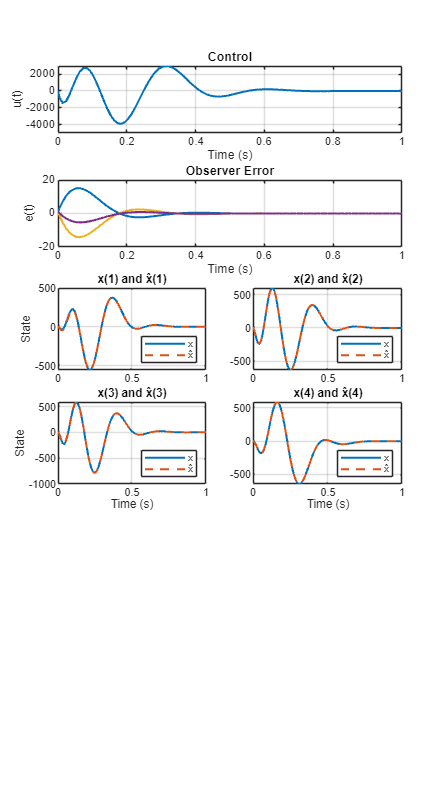

x0 = [1;1;1;1];
x0_hat = [0;0;0;0];
simulate_sys(A, B, C, K1, L1, x0, x0_hat, 1, 1)

### БОЛЬШЕ

x0 = [10; 10; 10];
Lj = syntLmin(Aj, Cj, 2, x0)

 
Calling SDPT3 4.0: 37 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of sdp    var  = 15,   num. of sdp  blk  =  4
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.8e+01|4.0e+00|3.2e+03| 9.997000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.599|0.612|7.3e+00|1.6e+00|1.4e+03|-2.487805e+02 -1.275068e+01| 0:0:01| chol  1  1 
 2|0.094|0.155|6.6e+00|1.3e+00|1.5e+03|-1.526740e+03 -4.850099e+01| 0:0:01| chol  1  1 
 3|0.180|0.346|5.4e+00|8.6e-01|1.7e+03|-2.333320e+03 -1.418200e

Lj =    -1.9997  -29.8223
    1.1213   10.9112
   -1.5975    0.0000


eig(Aj+Lj*Cj)

ans =   -2.0000 +12.3757i
  -2.0000 -12.3757i
  -2.3902 + 0.0000i


LJ = [Lj(1, 1) Lj(1, 2);
      Lj(2, 1) Lj(2, 2);
      0        0;
      Lj(3, 1) Lj(3, 2)]

LJ =    -1.9997  -29.8223
    1.1213   10.9112
         0         0
   -1.5975    0.0000


eig(AJ+LJ*CJ)

ans =   -2.0000 +12.3757i
  -2.0000 -12.3757i
  -2.3902 + 0.0000i
 -12.0000 + 0.0000i


L2=P*LJ

L2 =     1.5234   40.7335
    0.7192  -18.9112
   -4.7185  -40.7335
   -2.4759  -18.9112


eig(A+L2*C)

ans =   -2.0000 +12.3757i
  -2.0000 -12.3757i
 -12.0000 + 0.0000i
  -2.3902 + 0.0000i


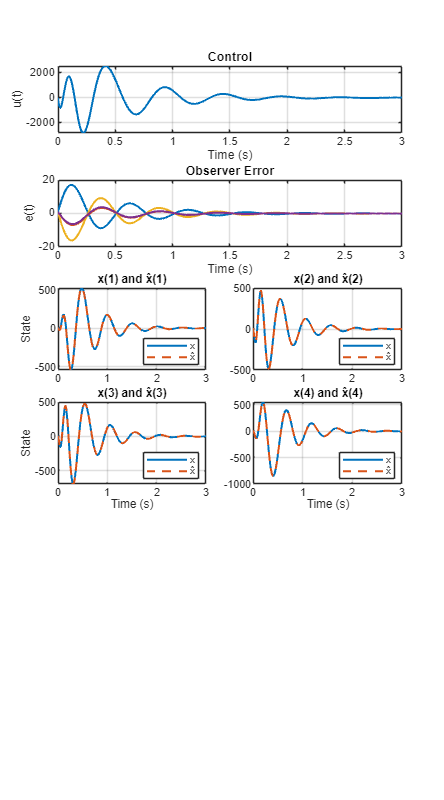

x0 = [1;1;1;1];
x0_hat = [0;0;0;0];
simulate_sys(A, B, C, K1, L2, x0, x0_hat, 3, 2);

### МЕНЬШЕ

K2 = syntKmin(A, B, 2, [0; 0; 0; 0])

 
Calling SDPT3 4.0: 50 variables, 15 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 15
 dim. of sdp    var  = 18,   num. of sdp  blk  =  4
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.3e+02|4.0e+01|2.8e+03| 9.999430e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.723|0.858|9.3e+01|5.7e+00|6.7e+02| 1.013188e+01 -1.353770e+01| 0:0:00| chol  1  1 
 2|0.616|0.648|3.6e+01|2.0e+00|3.3e+02| 1.046179e+01 -3.147250e+01| 0:0:00| chol  1  1 
 3|0.927|0.967|2.6e+00|6.7e-02|3.7e+01| 2.055104e+00 -2.220610e

K2 =    49.7464   25.9350  -55.5580   20.1232


eig(A+B*K2)

ans =   -2.0004 +12.2470i
  -2.0004 -12.2470i
 -11.9975 + 0.0000i
  -2.0004 + 0.0000i


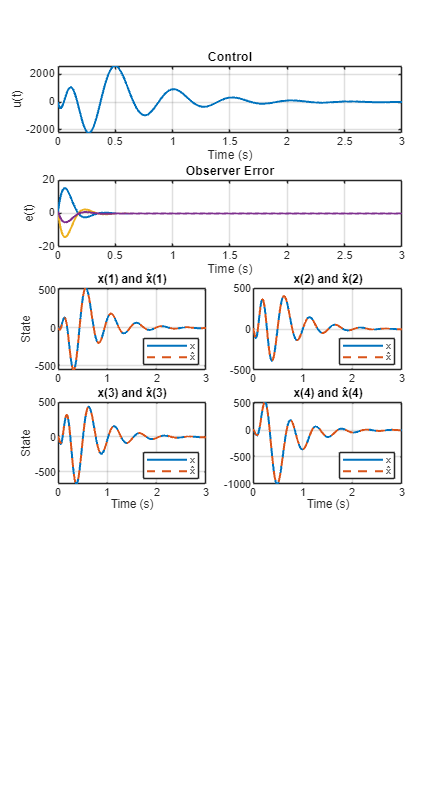

x0 = [1;1;1;1];
x0_hat = [0;0;0;0];
simulate_sys(A, B, C, K2, L1, x0, x0_hat, 3, 3);

## Задание 3. (Необязательное) Регулятор с качественной экспоненциальной устойчивостью.

function [K] = rik2(A, B, b, r, Q, R)
    syms P_ [2, 2]
    K_ = -inv(R+B'*P_*B)*B'*P_*(A-b*eye(2));
    eqs = (A+B*K_-b*eye(2))'*P_*(A+B*K_-b*eye(2))-r^2*P_ == -Q;
    s = vpasolve(eqs, [P_], Random=true)
    P = [s.P_1_1 s.P_1_2;
         s.P_2_1 s.P_2_2];
    K = -inv(R+B'*P*B)*B'*P*(A-b*eye(2));
end

A=[3 5 4;
    -2 -4 -5;
    2 2 3];
B=[2;-1;1];

[AJ, BJ, P1] = j_stuff_B(A, B)

Вещественная жорданова форма матрицы A:
    -2     0     0
     0     2    -1
     0     1     2

Вещественная P:
   -1.0000    0.7071   -0.7071
    1.0000   -1.4142         0
         0    1.4142         0

Вещественная P^{-1}:
         0    1.0000    1.0000
         0         0    0.7071
   -1.4142   -1.4142   -0.7071

Новая матрица B:
         0
    0.7071
   -2.1213



AJ =     -2     0     0
     0     2    -1
     0     1     2


BJ =          0
    0.7071
   -2.1213


P1 =    -1.0000    0.7071   -0.7071
    1.0000   -1.4142         0
         0    1.4142         0


Aj = [2 -1;
    1 2];
Bj = BJ(2:3);

b = -4;
r = 2;
Q = eye(2);
R = 1;
Kj = rik2(Aj, Bj, b, r, Q, R)

s = struct with fields:
    P_1_1: 1.0125
    P_2_1: 0.12916666666666666666666666666667
    P_1_2: -7.5791666666666666666666666666667
    P_2_2: -0.7625


$$Kj = \left(\begin{array}{cc} 0.083333333333333333333333333333333\,\sqrt{2} & 1.75\,\sqrt{2} \end{array}\right)$$

K1 = [0 Kj]/P1

$$K1 = \left(\begin{array}{ccc} -3.5 & -3.5 & -1.6666666666666666666666666666667 \end{array}\right)$$

K1 =[-0.63656542081698987466473125818447 -0.63656542081698987466473125818447 -9.9318192128799765060996349696426];
e1 = eig(A + B*K1)

e1 =   -3.2842 + 1.2648i
  -3.2842 - 1.2648i
  -2.0000 + 0.0000i


b = -4; r = 2;
Q = eye(2); R = 0;
Kj = rik2(Aj, Bj, b, r, Q, R)

s = struct with fields:
    P_1_1: -0.02248762520420478897387480218745
    P_2_1: -0.043024361874348124574822337187492
    P_1_2: -0.043024361874348124574822337187492
    P_2_2: 0.24320667970405029611976489412829


$$Kj = \left(\begin{array}{cc} 0.05491054388830944406650874416666\,\sqrt{2} & 1.9560385069297330701157645385526\,\sqrt{2} \end{array}\right)$$

K2 = [0 Kj]/P1

$$K2 = \left(\begin{array}{ccc} -3.9120770138594661402315290771053 & -3.9120770138594661402315290771053 & -1.901127963041423626049255794386 \end{array}\right)$$

K2 =[-0.58792298614053385976847092289474 -0.58792298614053385976847092289474 -10.765538703625243040617410872281];
e2 = eig(A + B*K2)

e2 =    -3.3535
   -4.0000
   -2.0000


b = -4; r = 2;
Q = 0; R = 1;
Kj = rik2(Aj, Bj, b, r, Q, R)

s = struct with fields:
    P_1_1: 13.513545634741245649757845895002
    P_2_1: 1.8814360596111111812800459303644
    P_1_2: -4.6510978530715519147323321573811
    P_2_2: -0.59139233501361865001274495289465


$$Kj = \left(\begin{array}{cc} -2.3966758858063122524763325040407\,\sqrt{2} & 1.3584195969779506969774211835725\,\sqrt{2} \end{array}\right)$$

K3 = [0 Kj]/P1

$$K3 = \left(\begin{array}{ccc} -2.716839193955901393954842367145 & -2.716839193955901393954842367145 & -3.7550954827842629494537536876133 \end{array}\right)$$

K3 =[-1 -1 -11];
e3 = eig(A + B*K3)

e3 =    -2.0000
   -6.0000
   -2.0000


b = -4; r = 2;
Q = 0; R = 0;
Kj = rik2(Aj, Bj, b, r, Q, R)

s = struct with fields:
    P_1_1: 2.2958874039497802890014385492622e-40
    P_2_1: 3.4438311059246704335021578238933e-41
    P_1_2: 7.346839692639296924804603357639e-40
    P_2_2: 1.3775324423698681734008631295573e-40


$$Kj = \left(\begin{array}{cc} 1.2876712328767123287671232876712\,\sqrt{2} & 2.1506849315068493150684931506849\,\sqrt{2} \end{array}\right)$$

K4 = [0 Kj]/P1

$$K4 = \left(\begin{array}{ccc} -4.3013698630136986301369863013699 & -4.3013698630136986301369863013699 & -0.8630136986301369863013698630137 \end{array}\right)$$

K4 =[-1.2761020881670533642691415313225 -1.2761020881670533642691415313225 -8.9303944315545243619489559164733];
e4 = eig(A + B*K4)

e4 =    -2.2065
   -4.0000
   -2.0000


th = 0:pi/50:2*pi;
xunit = r * cos(th) + b;
yunit = r * sin(th);
plot(xunit, yunit, 'k-', 'LineWidth', 1.5, 'DisplayName', 'Разброс'); hold on;
e = [e1 e2 e3 e4]; % Replace e1, e2, e3, e4 with your actual values
markers = {'o', 's', 'd', '^'}; % Circle, square, diamond, triangle
colors = {'r', 'g', 'b', 'm'};  % Red, green, blue, magenta
legends = {'Q=I, R=1', 'Q=I, R=0', 'Q=0, R=1', 'Q=0, R=0'}

legends = 1×4 cell array
    {'Q=I, R=1'}    {'Q=I, R=0'}    {'Q=0, R=1'}    {'Q=0, R=0'}


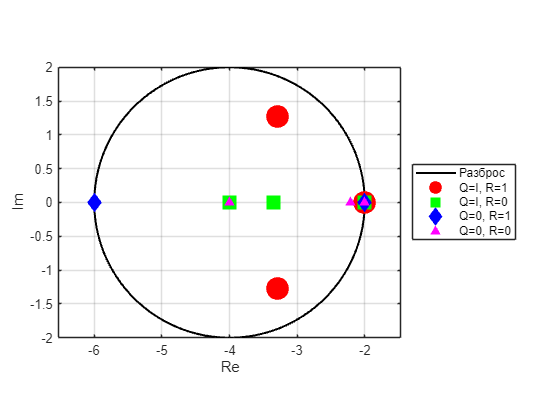

% Plot each point with its unique marker and color
for i = 1:4
    plot(real(e(:, i)), imag(e(:, i)), markers{i}, 'Color', colors{i}, ...
         'MarkerFaceColor', colors{i}, 'MarkerSize', 20 - 3.5*i, 'DisplayName', legends{i});
end
axis equal;
grid on;
xlabel('Re');
ylabel('Im');
hold off;
legend('Location', 'eastoutside');
exportgraphics(gcf, ['figs/task3', '.png'], 'Resolution', 500);

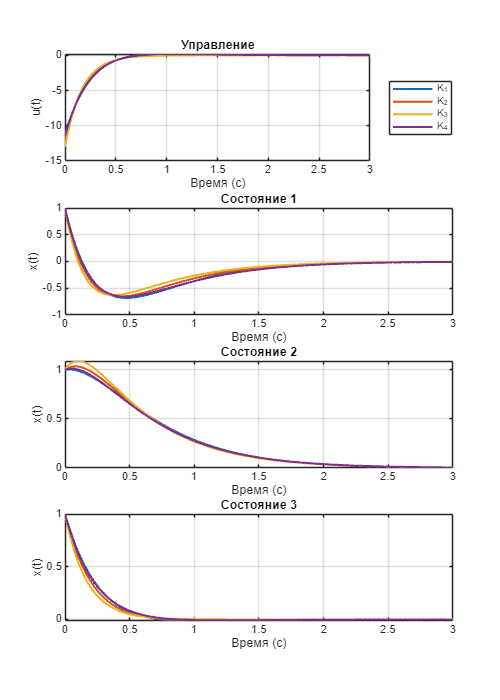

x0 = [1; 1; 1];
simulate(A, B, K1, K2, K3, K4, x0, 3, 'task31');